# **BSP 2021-2022/1 - Assignment 05**

  **Total of 10 marks**

**Name/Neptun Code: **** Hakan Burak KARLI/DMWBL1                                 **  

**Marks attained for this homework will count towards your final grade**

**To attain (full) marks for a question, any answer that includes images or a piece of knowledge, which should be referenced/cited, needs to highlight the source (book, article or web address). You are encouraged to help each other, but identical solutions will not be graded.**

**---------------------------------------------------------------------------------**

**In this assignment you get more freedom on how to solve the task compared to previous weeks.  This also means you need to explain your method of choice in detail.**

## Physiologic Response to Changes in Posture

The database "[Physiologic Response to Changes in Posture](https://archive.physionet.org/physiobank/database/prcp/)" includes ABP (arterial blood pressure, recorded  via FINAPRES volumeclamp BP measurement device),  a single channel ECG and posture-angle measurements. The subjects rested on a tilt table with foot support and subsequently underwent a series of six changes in posture: two stand-ups, two rapid HUTs (75◦ head-up tilt (HUT) over 2 secs), and two slow HUTs (75◦ HUT over 50 secs) each lasting for three minutes and separated by five minutes in the resting supine position.

In this assignment you will 

- evaluate the mean heart rate under different postures, by locating the systolic maximum pressure

- locate the dicrotic notches

## The measurement

Record 12819 was chosen for this task. 

**The datalines:**

*ch    name    gain           base        unit*

1	ABP	        64.02	4	        mmHg

2	ECG	6554	0	        mV

3	Angle	174.83	11204	degrees

**The annotation is:**

`Sample # 	Aux`

`116645 	        Initiation of rapid tilt up`

`117089    	Conclusion of rapid tilt up`

`171230   	Initiation of rapid tilt down`

`171589    	Conclusion of rapid tilt down`

`263050    	Stand-up`

`324651    	Transition back to supine`

`465749    	Initiation of slow tilt up`

`478249    	Conclusion of slow tilt up`

`530952    	Initiation of slow tilt down`

`543391    	Conslusion of slow tilt down`

`640373    	Stand-up`

`708849    	Transition back to supine`

`809598    	Initiation of rapid tilt up`

`809953    	Conclusion of rapid tilt up`

`862065    	Initiation of rapid tilt down`

`862448    	Conclusion of rapid tilt down`

`956427    	Initiation of slow tilt up`

`968896    	Conclusion of slow tilt up`

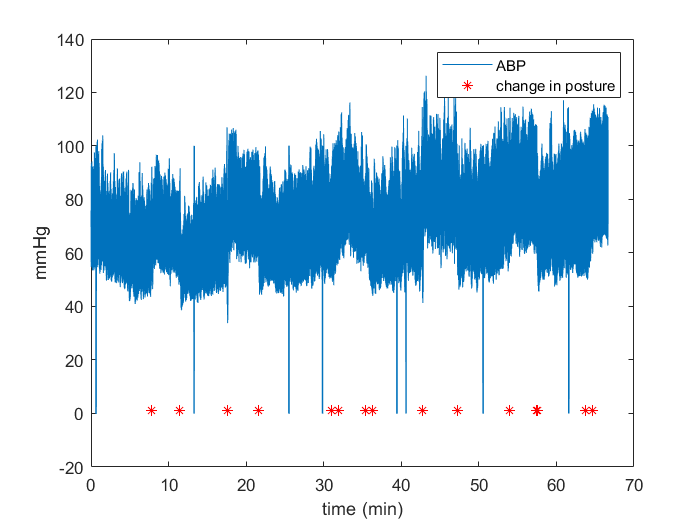

close all; clear all;
load 12819m.mat
fs = 250;

% shift = 280*fs;
Ns = size(val,2);

ABP = (val(1,:)-4)/64.02;
ECG = (val(2,:)-0)/6554;
Angle = (val(3,:)-11204)/174.83;

t = linspace(0,Ns/fs,Ns);

annot = [116645,117089,171230,171589,263050,324651,465749,478249,530952,...
    543391,640373,708849,809598,809953,862065,862448,956427,968896];%,...

plot(t/60,ABP)
hold on
plot(t(annot)/60,1,'r*')
xlabel('time (min)')
ylabel('mmHg')
legend('ABP','change in posture')

## Task 1

First you will need to locate the systolic peaks on the ABP data. Plot each phase of your algorithm. Some advices (you don't need to follow them):

- you might want to filter the dataline. A 1-10 Hz bandpass filter might suit you well. Don't forget to correct for filter delays.

- Differentiation can accentuate the changes.

- An envelope detection (eg. smoothing-based) helps to locate the peaks

- You can use findpeaks to locate the actual peaks on the envelope

- Using the found envelope peaks, find in their vicinity the actual ABP peaks  

- Don't go for perfection - a missed or extra peak here and there is ok.

An example output:

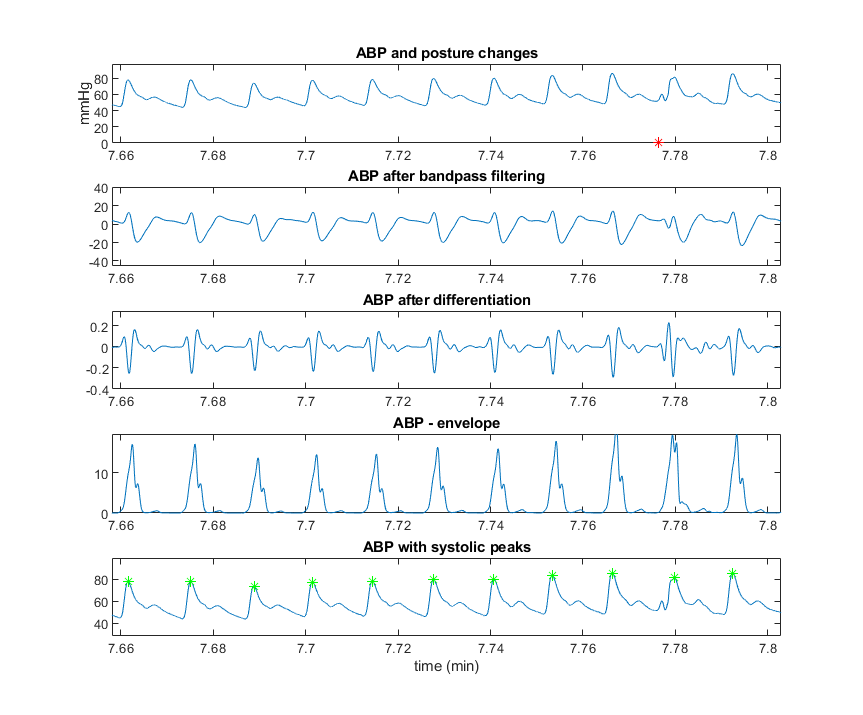

**Don't forget to explain your train of thoughts in detail .Discuss the advantages and faults of your algorithm is.**

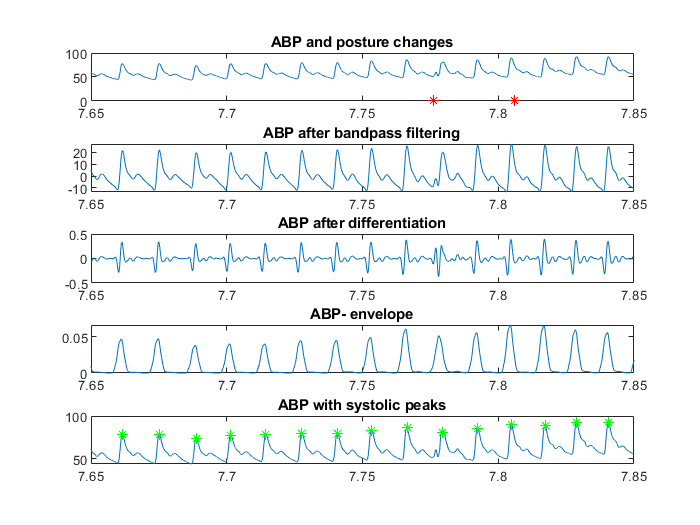


%filter part
%first tried cheby1 got some errors thenn used butterworth
%[b,a] = cheby1(10,0,[1 10]/(fs/2),'bandpass');
[b,a] =butter(3,[1, 10]/(fs/2),'bandpass');

filtABP = filtfilt(b, a, ABP);
%plot(t/60, filtABP)
%hold on
%xlim([7.65, 7.85])
%title("ABP after bandpass filtering")

% differentiation part
aDiff= 1;
bDiff= (1/8)*[2, 1, 0, -1, -2];
diffABP = filtfilt(bDiff, aDiff, filtABP);
%plot(t/60, diffABP)
%xlim([7.65, 7.85])
%title("ABP after differentiation")

%envelope detection
bEnvelope = ones(1, 30)/30;
aEnvelope = 1;
envelopeABP = filtfilt(bEnvelope, aEnvelope, diffABP.^2);
% plot(t/60, envelopeABP)
% xlim([7.65, 7.85])
% title("ABP- envelope")

% % find peaks

% [pks, locs] = findpeaks(envelopeABP, 'MinPeakHeight', 0.2);
% pksABP = zeros(1, length(locs));
% locsABP = zeros(1, length(locs));
% 
% for i=1:length(locs)
%     snip = locs(i)-20:locs(i)+20;
%     [pksABP(i),  l] = max(ABP(snip));
%     locsABP(i) = locs(i)+l-round(length(snip)/2);
% end


% I adopted the code we used in practice however it didn't work out. Now I
% will try something else. 
% I solved it. It didn't worked due to it goes
% after boundries

%find peak locs on detected envelope
[pks, locs] = findpeaks(envelopeABP, 'MinPeakHeight', 0.02);
pksABP = zeros(1, length(locs));
locsABP = zeros(1, length(locs));
% I realised that the prolem was window exceeds the signal in begininng and
% at the end so fix that I used if as you can see.
for i=1:length(locs)
   
   if locs(i)-20 < 1
       snip = 1:(locs(i)+20);
       
   elseif locs(i)+20 > size(ABP,2)
       snip = (locs(i)-20):length(ABP);    
   else  
    snip = locs(i)-20:locs(i)+20;
   end
   [pksABP(i),  l] = max(ABP(snip));
   locsABP(i) = locs(i)+l-round(length(snip)/2);
end
%plotting part
figure;
subplot(5, 1, 1)
plot(t/60, ABP)
hold on
plot(t(annot)/60,1,'r*')
xlim([7.65, 7.85])
title("ABP and posture changes")
subplot(5, 1, 2)
plot(t/60, filtABP)
xlim([7.65, 7.85])
title("ABP after bandpass filtering")
subplot(5, 1, 3)
plot(t/60, diffABP)
xlim([7.65, 7.85])
title("ABP after differentiation")
subplot(5, 1, 4)
plot(t/60, envelopeABP)
xlim([7.65, 7.85])
title("ABP- envelope")
subplot(5, 1, 5)
plot(t/60, ABP)
hold on
plot(t(locsABP)/60, pksABP, 'g*')
xlim([7.65, 7.85])
title("ABP with systolic peaks")

(4 marks)

## Task 2

Calculate the heart rate from the location of the systolic peaks (inverse difference between two subsequent peaks) . Calculate the mean heartrate for  each posture (`annot` array holds the location of these changes). Plot your results.

- The dataset is noisy, and the peakdetection might have been imperfect. Feel free to smooth your output heartrate dataline in order to exclude outliers

An example output:

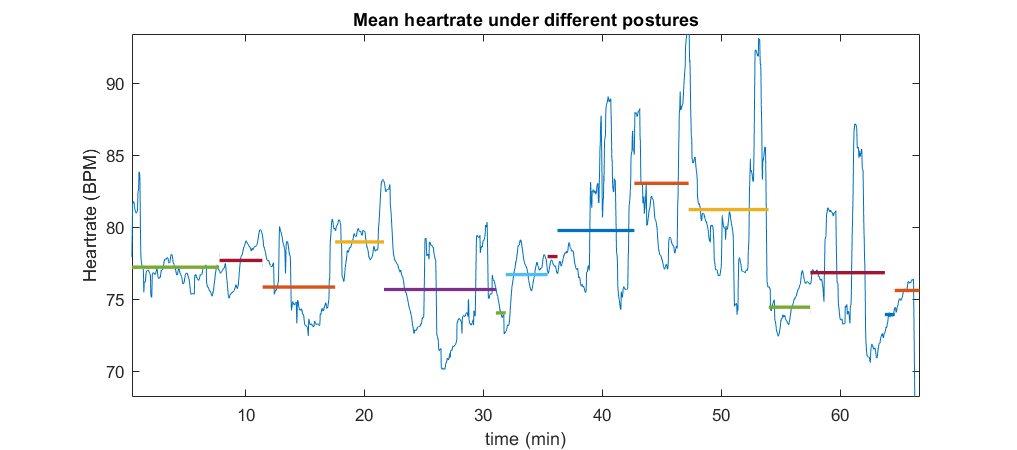

**Don't forget to explain your train of thoughts in detail. Discuss the advantages and faults of your algorithm is.**

%first we need to take inverse difference between two subsequent 
%peaks

[noise_exc_locs,logical_locsABP] = rmoutliers(locsABP);
% Accidentally I put * instead of .* so it was a hard error to see and
% correct
%   temp = locsABP * (~(logical_locsABP))
%   temp = locsABP .* (~(logical_locsABP));
%      also first I was going to use above code then I realized that I can  use B
%      which is excluded values for getting rid of the noise
temp = locsABP .* (~(isoutlier(noise_exc_locs)))

temp =          426         624         822        1023        1222        1420        1614        1803        1988        2170        2355        2546        2737        2927        3113        3302        3491        3679        3872        4072        4274        4468        4665        4866        5068        5266        5459        5654        5852        6049        6623        6819        7014        7204        7395        7589        7784        7971        8161        8349        8534        8723        8915        9096        9218        9389        9468        9639        9718        9889


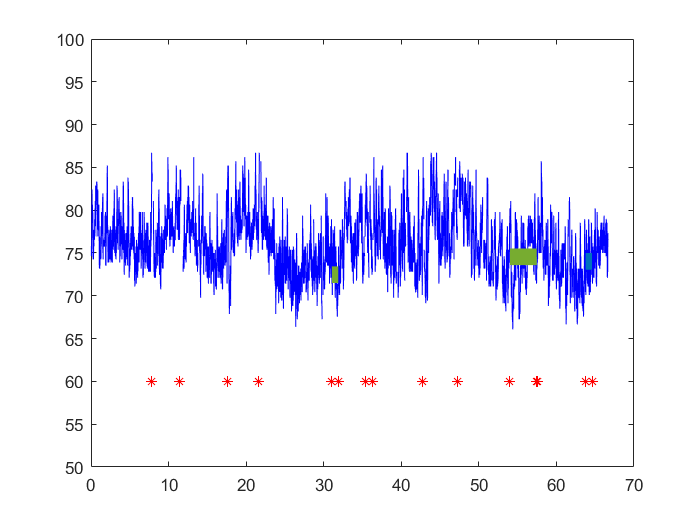

HR = [];
MHR = [];

for i = 1:(length(temp)-1)
    HR(i) = 1/((t(locsABP(i+1))/60)-(t(locsABP(i))/60)); 
end

HR = HR .* (~(isoutlier(HR)));

%sum = sum(HR(:));

sum = sum(HR(1:length(HR)),'all');
%because when I tried to sum them up I faced a problem which is about I got
%NAN values due division by 0.
notzero = length(find(HR~=0));
for i=1:length(HR)
 if HR(i)==0
 MHR(i) = sum/notzero;
 else
  MHR(i) = HR(i);   
 end
MHR = [MHR, mean(MHR)];
end

meanval = zeros(1,length(annot));
% I was trying to choose a window for selecting avarage values however I
% made a mistake which I don't know where, If I can ask on Friday, I would
% be gretaful.
chosenwindow = cell(1, length(annot));
for i=1:length(annot)-1
 chosenwindow(i) = {locsABP(annot(i)<=locsABP & locsABP<=annot(i+1))};
 index = find(annot(i)<=locsABP & locsABP<=annot(i+1)); 
 if length(index) > 1
 meanval(i) = mean(MHR(index(1):index(end)));
 else 
 meanval(i) = MHR(index);
 end
end

figure;
plot(t(locsABP)/60, MHR, 'b');
hold on
plot(t(annot)/60,60,'r*')
for i=1:length(meanval)
 plot(t(chosenwindow{i})/60, meanval(i)*ones(1, length(chosenwindow{i})), 'LineWidth', 10);
end
ylim([50, 100]);

;

(3 marks)

## Task 3

Locate the dicrotic notches on your dataline. Plot your results.

An example output:

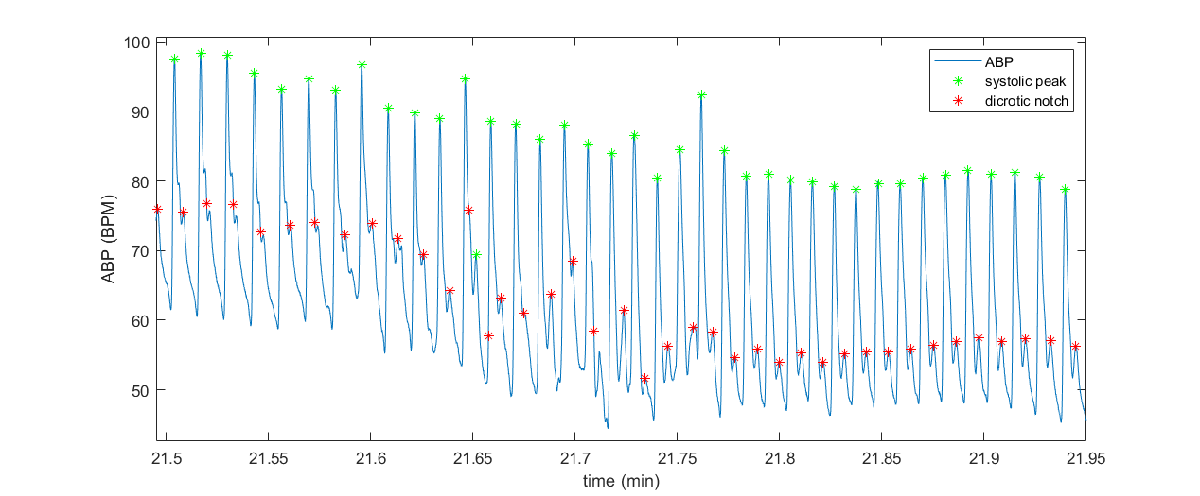

**Don't forget to explain your train of thoughts in detail. Discuss the advantages and faults of your algorithm is.**

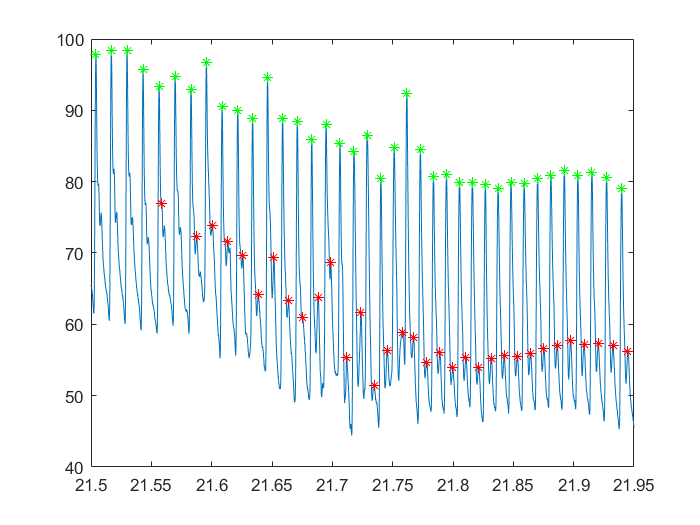

% I couldn't decide which value should it take so I started giving number
% from 15 to 20 
[pks, locs] = findpeaks(filtABP, "MinPeakDistance",20);

pksOffset = [0, pks(1:end-1)];
sysLocs = locs(pks>10);
sysPks = pks(pks>10);
dicLocs = locs(pks<5 & abs(pksOffset-pks) >15 );
dicPks = pks(pks<5 & abs(pksOffset-pks) >15);
figure
plot(t/60, ABP)
hold on
plot(t(sysLocs)/60, ABP(sysLocs),'g*')
plot(t(dicLocs)/60, ABP(dicLocs),'r*')
xlim([21.5, 21.95])

(3 marks)

**Do not forget to generate a pdf report from this file (Save/ Export to PDF). You should upload both the pdf and mlx files to moodle.**